# Diagnostics - USRP Sensing Subsystem

## Configure the configuration to test against

clear;
clf;
simulator = Simulator_revB();
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/BlackBoxRadarAttacks/MATLAB/config_files/";
% file_path = "20MHz_USRP.json";
file_path = "20MHz_USRP_100us.json";
% file_path = "20MHz_USRP_revB.json";
% file_path = "20MHz.json";
% file_path = "100MHz.json";
% file_path = "100MHz_USRP.json";
% file_path = "1GHz.json";
% file_path = "4GHz.json";
simulator.load_params_from_JSON(david_path + file_path);

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_usrp_attacker_and_victim_position_and_velocity();

%print out key parameters

simulator.Victim.print_radar_parameters;

Chirp Parameters
	 Start Frequency: 		 1.50 GHz
	 Frequency Slope: 		 0.25 MHz/us
	 Idle Time: 			 1.80 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.48 us
	 ADC Samples: 			 256 
	 ADC Sample Rate: 		 2.78 MSps
	 Ramp End Time: 		 98.64 us
	 Chirp Tx Bandwidth: 		 25.00 MHz
	 Chirp Sampling Bandwidth: 	 23.36 MHz
	 ADC Sampling Period: 		 92.16 us
	 Chirp Cycle Time: 		 100.44 us
	 Chirp Wavelength: 		 199.86 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 150.06 ms
	 Active Frame Time 		 25.71 ms
Performance Specifications
	 Max Range 			 1642.86 m
	 Range Resolution 		 6.42 m
	 Max Velocity 			 497.47 m/s
	 Velocity Resolution 		 3.89 m/s
FMCW Specifications
	 FMCW sampling rate 		 25.00 MHz
	 Downsampling factor 		 9
	 Sweep time 			 98.64 us
	 Samples per chirp 		 2511.00 
CFAR Detection Region
	 Range Detection Region 		 44.922 m to 1591.523 m
	 Velocity Detection Region 		 -439.169 m/s to 443.055 m/s


### Save the victim chirp to a file

%save the full chirp as a binary file
path = "/home/david/Documents/MATLAB_generated/MATLAB_full_chirps/MATLAB_chirp_full.bin";
simulator.save_to_file(simulator.Victim.chirp,path,'float32');

### Plot Tx Chirp to confirm correctness

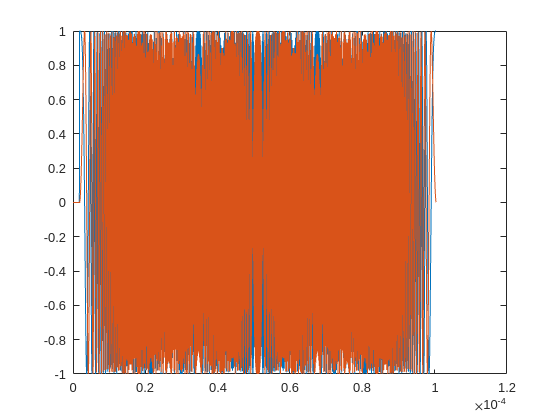

%plot the chirp signal
t = 0:simulator.Victim.FMCW_sampling_period_s:...
    simulator.Victim.ChirpCycleTime_us * 1e-6 - ...
    simulator.Victim.FMCW_sampling_period_s;
data = simulator.Victim.chirp;
plot(t,real(data),t,imag(data))

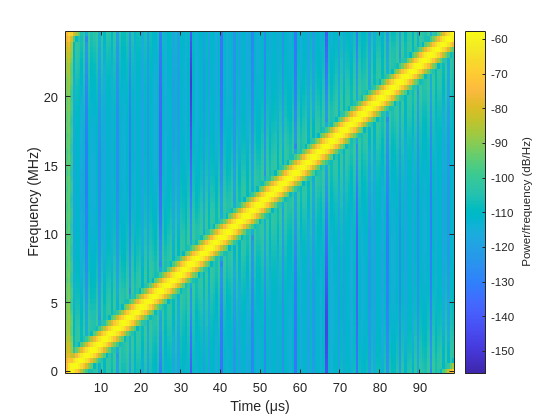

spectrogram(data,64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

## RUN EXPERIMENT ON USRP DEVICE - SESING ONLY (enable debug on sensing subsystem)

### Load key sensing subsystem parameters from USRP Implementation

### Spectrogram Generation

#### Get key initialization parameters

num_rows = 580;
fft_size = 128;
samples_per_sampling_window = 130;
samp_freq = 25.000 * 1e6;

%load the times/frequencies used for spectrogram generation in the cpp code
path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_spectrogram_times.bin";
spectrogram_times = simulator.read_from_file(path,false,"double");

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_spectrogram_frequencies.bin";
spectrogram_frequencies = simulator.read_from_file(path,false,"double");

fprintf(" rows: %d \n samples per sampling window: %d \n fft size: %d \n samp freq: %d",...
    num_rows,samples_per_sampling_window,fft_size,samp_freq);

 rows: 580 
 samples per sampling window: 130 
 fft size: 128 
 samp freq: 25000000

#### Verify Hanning Window

%get the hanning window
path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_hanning_window.bin";
read_data = simulator.read_from_file(path,true,"float");

%compare with the computed hanning window
compare = all(abs(read_data - hann(fft_size)) < 1e-5);
if compare
    fprintf("Hanning window matches")
else
    fprintf("Hanning window doesn't match")
end

Hanning window matches

#### Reshape Received Signal - read and verify

%get the reshaped for fft signal
path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_reshaped_and_windowed_for_fft.bin";

read_data = simulator.read_from_file(path,true,"float");
read_data_reshaped = reshape(read_data,fft_size,num_rows);

#### Generated Spectrogram

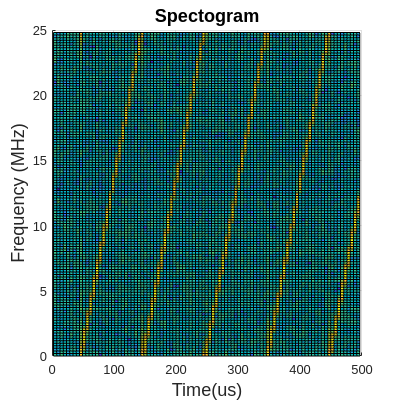

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_generated_spectrogram.bin";

read_data = simulator.read_from_file(path,false,"float");
read_data_reshaped = reshape(read_data,fft_size,num_rows);

max_time_to_plot_us = 500;
idx_to_plot = spectrogram_times < max_time_to_plot_us;

clf;
set(gcf,'Position',[100 100 400 400])
font_size = 14;
ax = gca;
ax.FontSize = font_size;
surf(spectrogram_times(idx_to_plot),...
    spectrogram_frequencies,...
    read_data_reshaped(:,idx_to_plot));
title_str = sprintf('Spectogram');
title(title_str,"FontSize",font_size);
xlabel('Time(us)',"FontSize",font_size)
ylabel('Frequency (MHz)',"FontSize",font_size)
view([0,90.0])

#### Detected Times and Frequencies - read and verify

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_detected_frequencies.bin";

read_data_detected_frequencies = simulator.read_from_file(path,false,"double");

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_detected_times.bin";
read_data_detected_times = simulator.read_from_file(path,false,"double");

#### Clusters - read and verify

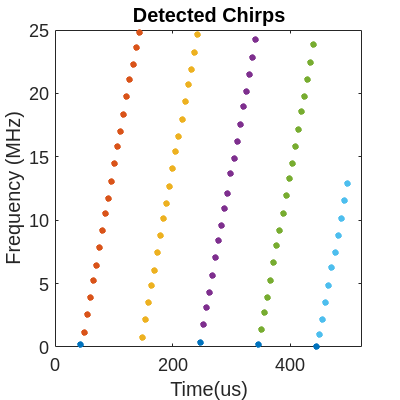

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_computed_clusters.bin";
read_data = simulator.read_from_file(path,false,"int");
read_data_idx = read_data(read_data ~= 0);

idx_to_plot = read_data_detected_times < max_time_to_plot_us;

clf;

gscatter(read_data_detected_times(idx_to_plot), ...
    read_data_detected_frequencies(idx_to_plot), ...
    read_data_idx(idx_to_plot));
set(gcf,'Position',[100 100 400 400])
font_size = 14;
title_str = sprintf('Detected Chirps');
title(title_str,"FontSize",font_size);
xlabel('Time(us)',"FontSize",font_size)
ylabel('Frequency (MHz)',"FontSize",font_size)
ax = gca;
ax.FontSize = font_size;
legend off;

#### Computed Linear Models

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_detected_slopes.bin";
read_data_detected_slopes = simulator.read_from_file(path,false,"double")

read_data_detected_slopes =     0.2531
    0.2537
    0.2537
    0.2536
    0.2534
    0.2537
    0.2535
    0.2528
    0.2535
    0.2535




path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_detected_intercepts.bin";
read_data_intercepts = simulator.read_from_file(path,false,"double")

read_data_intercepts = 1.0e+06 *

    3.1502
    3.1503
    3.1504
    3.1505
    3.1506
    3.1507
    3.1508
    3.1509
    3.1510
    3.1511


%captured chirps buffer
path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_chirp_estimates.bin";
captured_chirps_buffer = simulator.read_from_file(path,false,"double");
%captured slopes buffer
path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_slope_estimates.bin";
captured_slopes_buffer = simulator.read_from_file(path,false,"double");
%captured frames buffer
path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_frame_estimates.bin";
captured_frames_buffer = simulator.read_from_file(path,false,"double");

#### Captured Frames Array

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_captured_frames.bin";
read_data = simulator.read_from_file(path,false,"double");
captured_frames = reshape(read_data,6,[]).'

captured_frames = 1.0e+06 *

         0         0         0         0    0.2502         0
         0         0         0         0    0.3502    0.4503
         0         0         0         0    0.4502    0.5503
         0         0         0         0    0.5502    0.6503
         0         0         0         0    0.6502    0.7503
         0         0         0         0    0.7502    0.8503
         0         0         0         0    0.8502    0.9503
         0         0         0         0    0.9502    1.0503
         0         0         0         0    1.0502    1.1503
         0         0         0         0    1.1502    1.2503


estimation_errors_ns = (captured_frames(2:end - 1,6) - captured_frames(3:end,5) ...
    - simulator.Victim.ChirpCycleTime_us) * 1e3

estimation_errors_ns =  -236.4971
 -100.4300
  -64.9887
  -25.3892
    5.5527
    6.7462
    7.6160
  -32.3530
   12.3596
   12.1298


average_error_ns = mean(estimation_errors_ns(3:end))

average_error_ns = 1.1522

error_stdev_ns_squared = sqrt(var(estimation_errors_ns(3:end)))

error_stdev_ns_squared = 23.4688

### Get the estimated parameters

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_estimated_parameters.bin";
read_data = simulator.read_from_file(path,false,"double");
estimated_frame_duration_ms = read_data(1);
estimated_chirp_duration_us = read_data(2);
estimated_chirp_slope_MHz_us = read_data(3);

% %print out the relevant information
fprintf("Average Frame Duration: %3.7f ms",estimated_frame_duration_ms);

Average Frame Duration: 99.9998557 ms

fprintf("Average Chirp Duration: %3.3f us",estimated_chirp_duration_us);

Average Chirp Duration: 100.450 us

fprintf("Average Slope: %1.3f MHz/us",estimated_chirp_slope_MHz_us);

Average Slope: 0.253 MHz/us

### Estimation Errors

% %print out the relevant information
actual_frame_duration_ms = 150;
fprintf("Frame Duration Error: %3.5f ns",(estimated_frame_duration_ms - actual_frame_duration_ms) * 1e6);

Frame Duration Error: -50000144.31031 ns

fprintf("Chirp Duration Error: %3.5f ns",(estimated_chirp_duration_us - simulator.Victim.ChirpCycleTime_us) * 1e3);

Chirp Duration Error: 10.06101 ns

fprintf("Slope Error: %1.5f MHz/us",estimated_chirp_slope_MHz_us - simulator.Victim.FrequencySlope_MHz_us);

Slope Error: 0.00002 MHz/us

### Computed Victim Waveform from Attacker

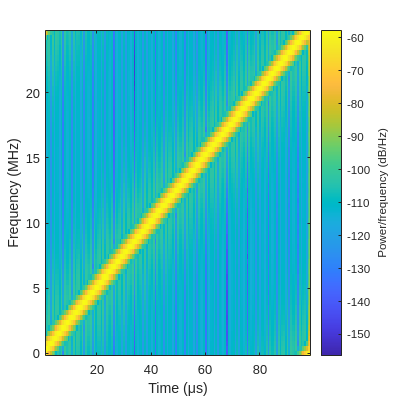

clf;
path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_computed_victim_waveform.bin";
estimated_waveform = simulator.read_from_file(path,true,"float32");
spectrogram(estimated_waveform,64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

### Computed Cross-Correlation

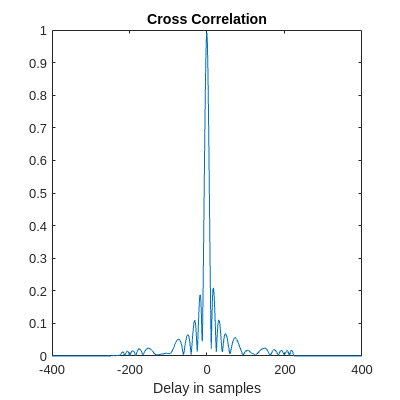

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cross_correlation_result.bin";
result = simulator.read_from_file(path,true,"float32");

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cross_correlation_lags.bin";
lags = simulator.read_from_file(path,false,"int");

%plot the computed cross correlation
clf;
plot(lags,abs(result));
xlabel("Delay in samples")
title("Cross Correlation")